#                                                                   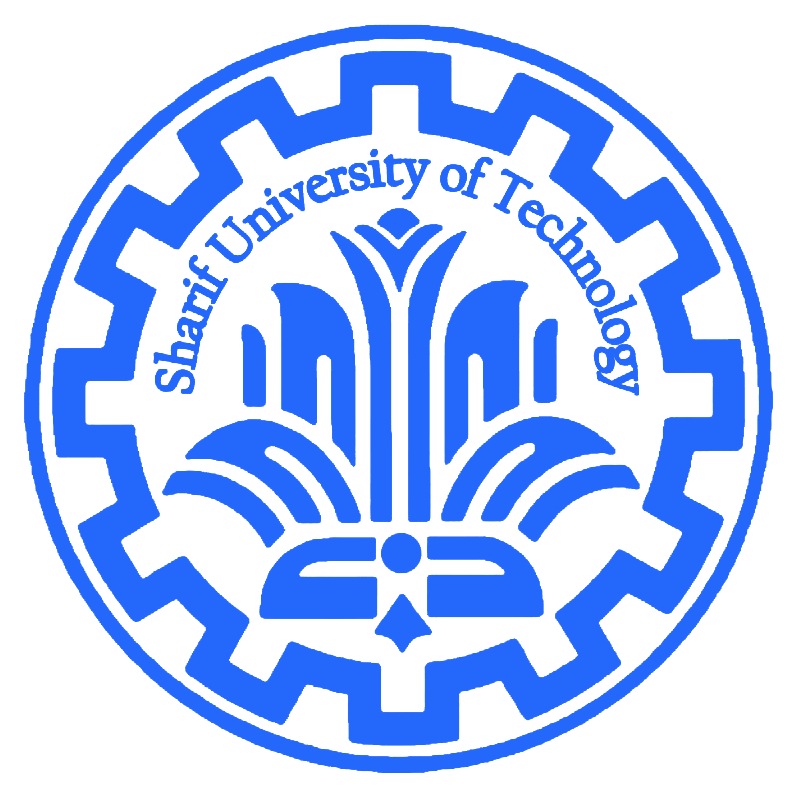

# 
$$\textbf{Stochastic Processes}
$$


# 
$$\text{Computer Assignment \#3
}
$$


#### 
$$\textit{Masoud Tahmasbi Fard - 402200275
}$$


### 
$$\textbf{Question \#1}$$


**............................................................................................................**

### 
$$\text{Part A}.$$
 

.............................................................................................................

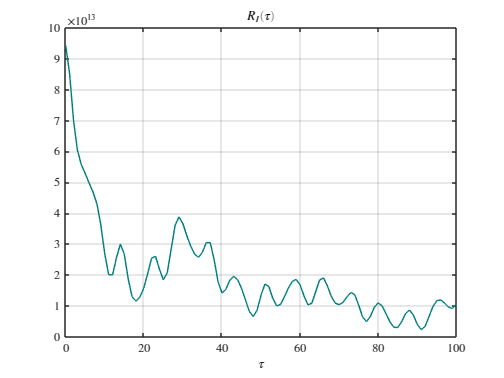

data = load("f16.mat").f16;
tau = 100;

[R_I,lags] = xcorr(data,data,tau);

figure
plot(lags(tau+1:end),R_I(tau+1:end),'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$R_I(\tau)$','interpreter','latex')
xlabel('$\tau$','interpreter','latex')
grid on;

### 
$$\text{Part B}.$$
 

.............................................................................................................

estimation_2 = ar(data,2)

estimation_2 =
Discrete-time AR model: A(z)y(t) = e(t)
  A(z) = 1 - 1.263 z^-1 + 0.3975 z^-2  
                                       
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using AR ('fb/now') on time domain data "data".
Fit to estimation data: 60.68%                           
FPE: 3.098e+06, MSE: 3.098e+06                           


estimation_4 = ar(data,4)

estimation_4 =
Discrete-time AR model: A(z)y(t) = e(t)                           
  A(z) = 1 - 1.447 z^-1 + 0.9584 z^-2 - 0.4942 z^-3 + 0.07049 z^-4
                                                                  
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using AR ('fb/now') on time domain data "data".
Fit to estimation data: 63.95%                           
FPE: 2.604e+06, MSE: 2.604e+06                           


### 
$$\text{Part C}.$$
 

.............................................................................................................

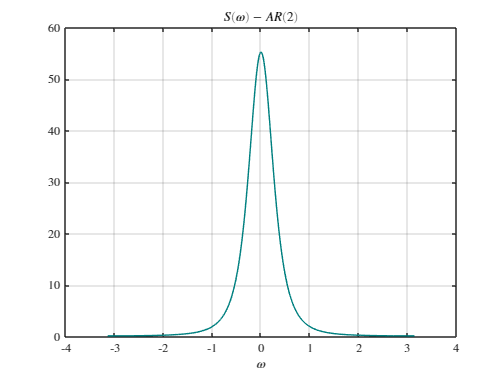

L = 1000;
omega = linspace(-1, 1, L)*pi;
z = exp(1i.*omega);
L_z = 1./( 1 - 1.263*z.^(-1) +0.3975*z.^(-2) );
S_w_2 = abs(L_z).^2;

figure
plot(omega,S_w_2,'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
title('$S(\omega) - AR(2)$','interpreter','latex')
grid on;

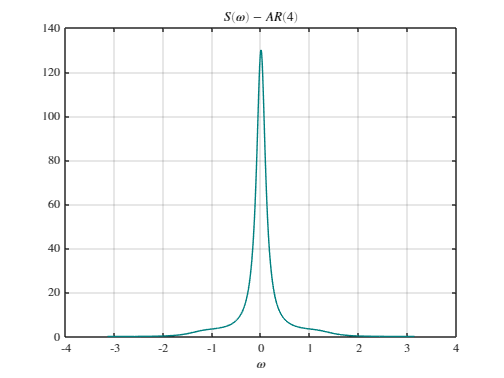

L_z = 1./( 1 - 1.447*z.^(-1) + 0.9584*z.^(-2) - 0.4942*z.^(-3) + 0.07049*z.^(-4) );
S_w_4 = abs(L_z).^2;

figure
plot(omega,S_w_4,'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
title('$S(\omega) - AR(4)$','interpreter','latex')
grid on;

### 
$$\text{Part D}.$$
 

.............................................................................................................

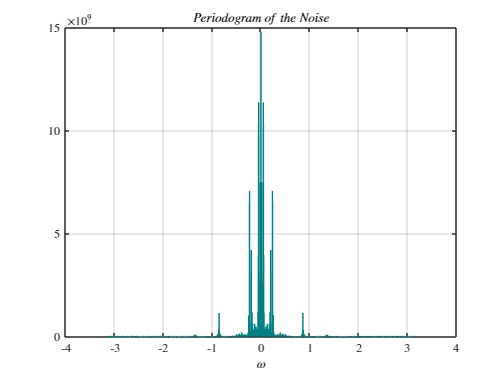

[pxx,w] = periodogram(data);
figure
plot([-flip(w);w],[flip(pxx);pxx],'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
title('$Periodogram\;of\;the\;Noise$','interpreter','latex')
grid on;

### 
$$\text{Part E}.$$
 

.............................................................................................................

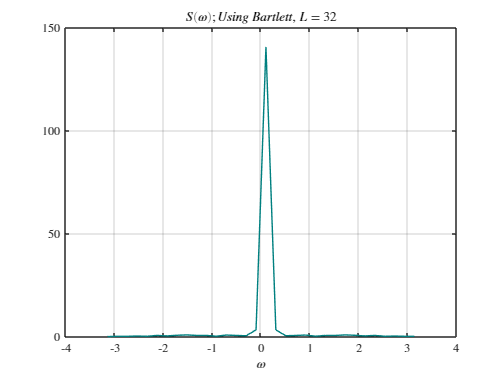

L = 32;
M = round(length(data)/L);
I_m = zeros(L,M);
omega = linspace(-1, 1, L)*pi;

for m = 0:M-1
    x_m = data(m*L+1:(m+1)*L);
    I_m(:,m+1) = (1/L)*fftshift(fft(x_m));
end
S_32 = mean(I_m,2);


figure
plot(omega,abs(S_32),'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
title('$S(\omega);\; Using\;Bartlett,\;L = 32$','interpreter','latex')
grid on;

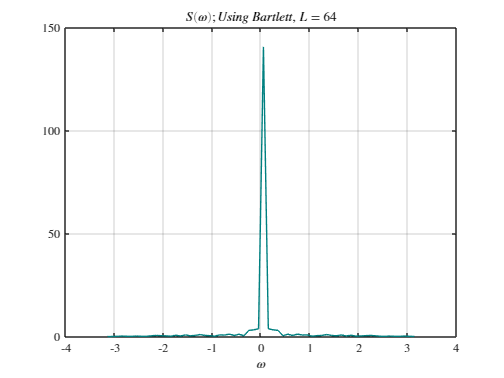

L = 64;
M = round(length(data)/L);
I_m = zeros(L,M);
omega = linspace(-1, 1, L)*pi;

for m = 0:M-1
    x_m = data(m*L+1:(m+1)*L);
    I_m(:,m+1) = (1/L)*fftshift(fft(x_m));
end
S_64 = mean(I_m,2);


figure
plot(omega,abs(S_64),'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
title('$S(\omega);\; Using\;Bartlett,\;L = 64$','interpreter','latex')
grid on;

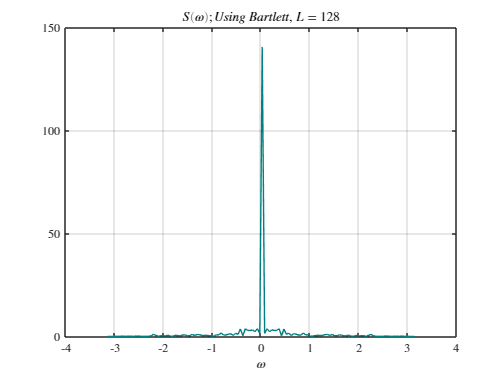

L = 128;
M = round(length(data)/L);
I_m = zeros(L,M);
omega = linspace(-1, 1, L)*pi;

for m = 0:M-1
    x_m = data(m*L+1:(m+1)*L);
    I_m(:,m+1) = (1/L)*fftshift(fft(x_m));
end
S_128 = mean(I_m,2);


figure
plot(omega,abs(S_128),'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
title('$S(\omega);\; Using\;Bartlett,\;L = 128$','interpreter','latex')
grid on;

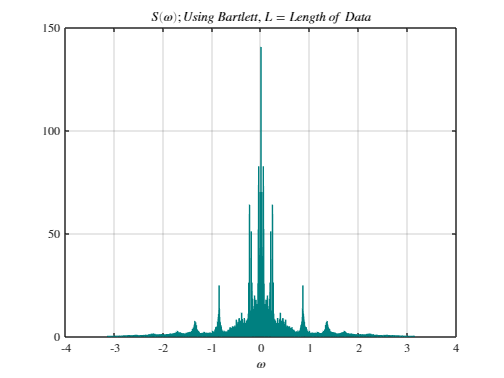

L = length(data);
M = round(length(data)/L);
I_m = zeros(L,M);
omega = linspace(-1, 1, L)*pi;

for m = 0:M-1
    x_m = data(m*L+1:(m+1)*L);
    I_m(:,m+1) = (1/L)*fftshift(fft(x_m));
end
S_all = mean(I_m,2);


figure
plot(omega,abs(S_all),'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
title('$S(\omega);\; Using\;Bartlett,\;L = Length\;of\;Data$','interpreter','latex')
grid on;

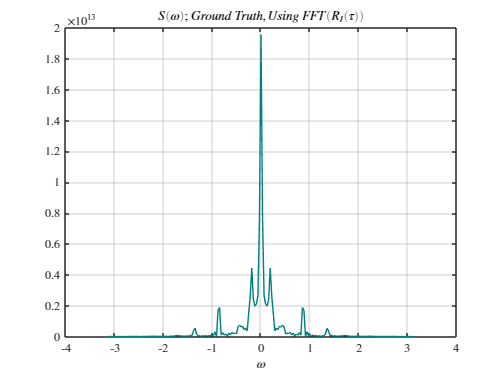

S_w = (1/length(R_I))*fftshift(fft(R_I));
omega = linspace(-1, 1, length(S_w))*pi;

figure
plot(omega,abs(S_w),'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
title('$S(\omega);\;Ground\;Truth,\; Using\;FFT(R_I(\tau))$','interpreter','latex')
grid on;

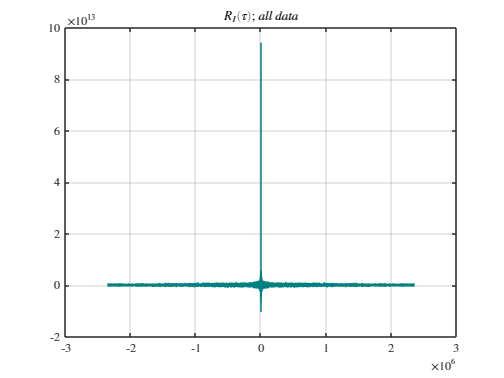

data = load("f16.mat").f16;
tau = round(length(data)/2);

[R_I_1,lags_1] = xcorr(data,data,tau);

figure
plot(lags_1,R_I_1,'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$R_I(\tau);\;all\;data$','interpreter','latex')
grid on;

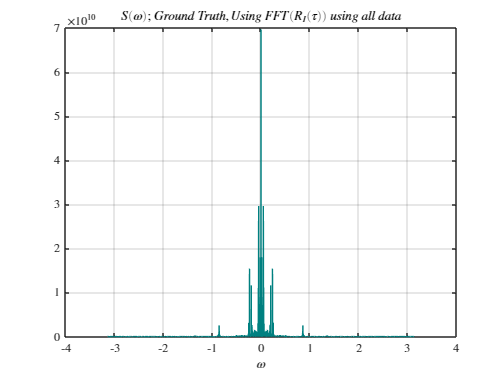

S_w_1 = (1/length(R_I_1))*fftshift(fft(R_I_1));
omega_1 = linspace(-1, 1, length(S_w_1))*pi;

figure
plot(omega_1,abs(S_w_1),'Color','#008080')

ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
title('$S(\omega);\;Ground\;Truth,\; Using\;FFT(R_I(\tau))\; using\;all\;data$','interpreter','latex')
grid on;